# E7 bis

# Segmentació de la imatge

### Segmentació assistida

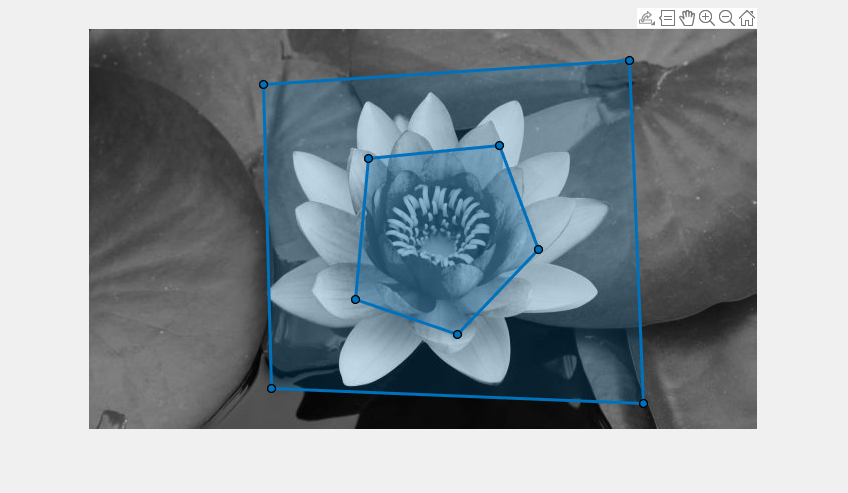

I = rgb2gray(imread('nenufar.jpg'));
imshow(I);
roiPoints = drawpolygon;
[f,c] = size(I);
BK = not(poly2mask(roiPoints.Position(:,1),roiPoints.Position(:,2),f,c));
roiPoints = drawpolygon;

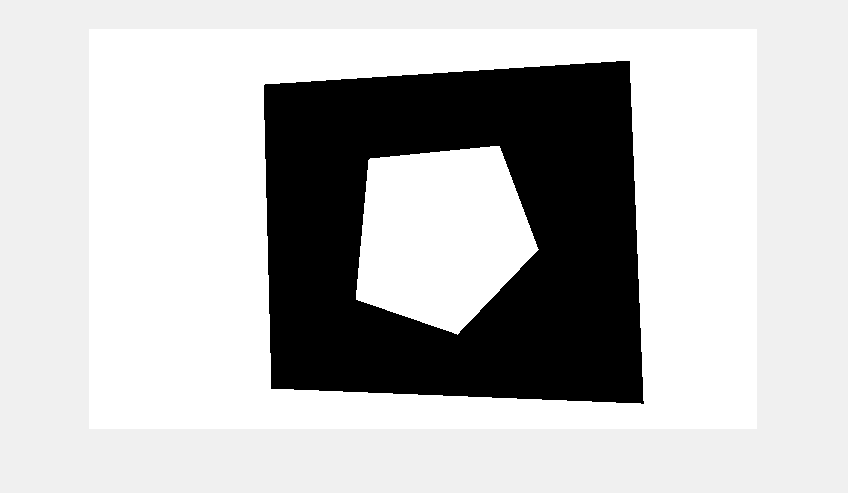

FG = poly2mask(roiPoints.Position(:,1),roiPoints.Position(:,2),f,c);

MASK = BK|FG;
imshow(MASK);

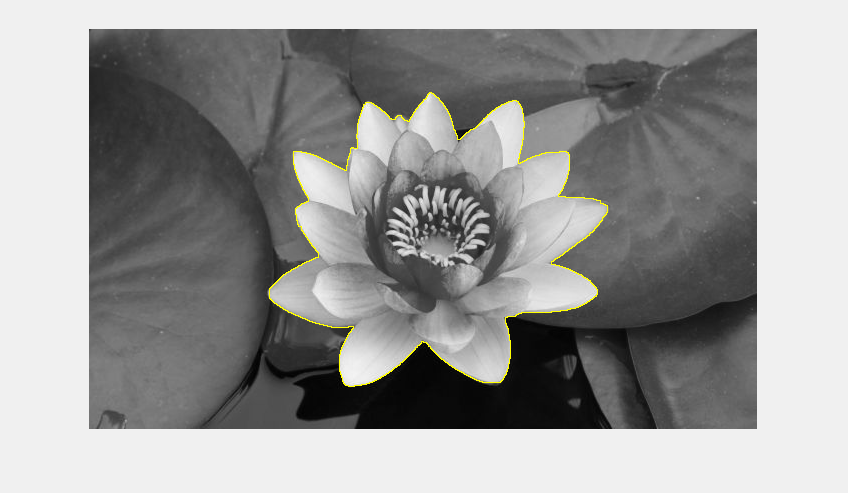


Grad = uint8(imgradient(I));

% markers
G = imimposemin(Grad,MASK);

WS = watershed(G);
imshow(imoverlay(I,(WS == 0)),[]);

### Segmentació assistida utilitzant graph min cut

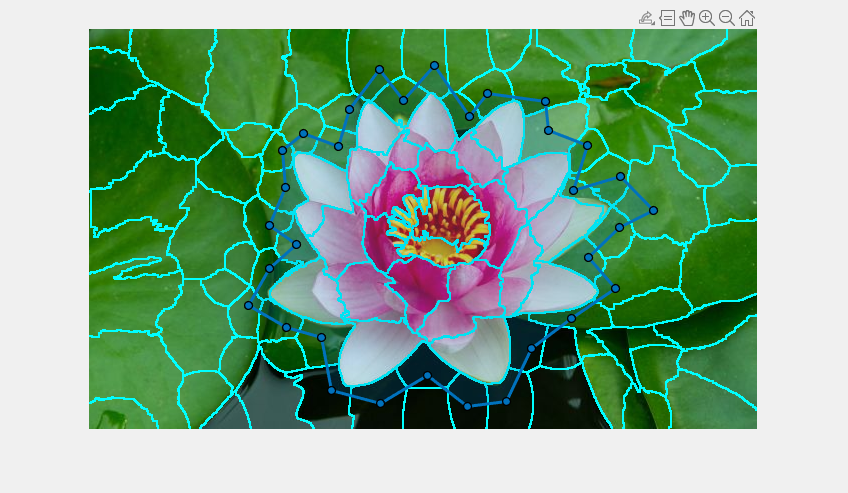

I = imread('nenufar.jpg');
[SP,N] = superpixels(I,100);
BW = boundarymask(SP);
imshow(imoverlay(I,BW,'cyan'));

[f,c,z] = size(I);
roiPoints = drawpolygon;

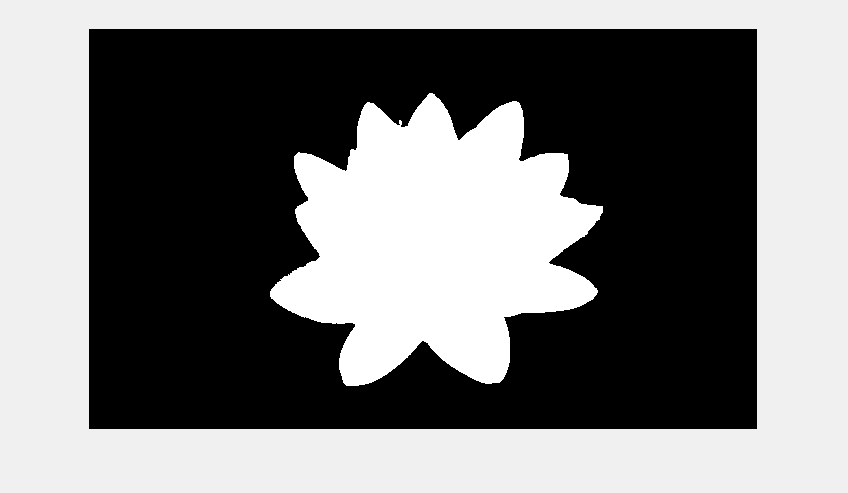

roi = poly2mask(roiPoints.Position(:,1),roiPoints.Position(:,2),f,c);
BW = grabcut(I,SP,roi);
imshow(BW);

### Segmentacio en base a una area (rectangle)

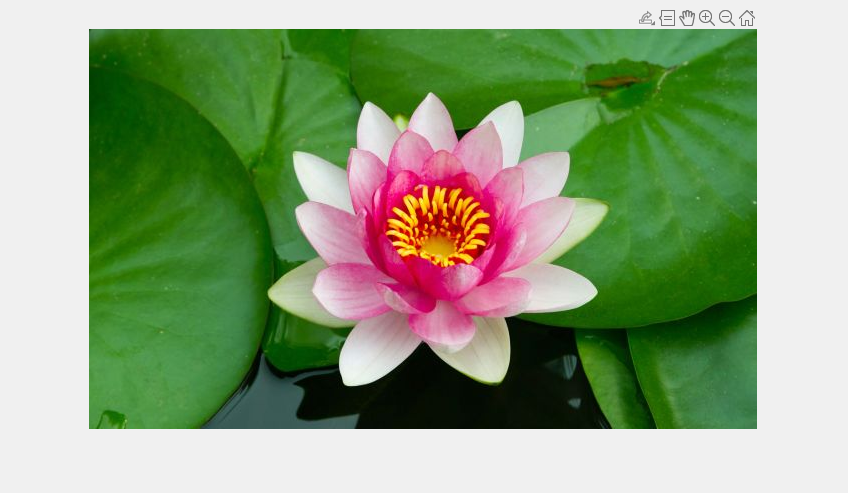

I = imread('nenufar.jpg');
imshow(I);
rect = getrect;

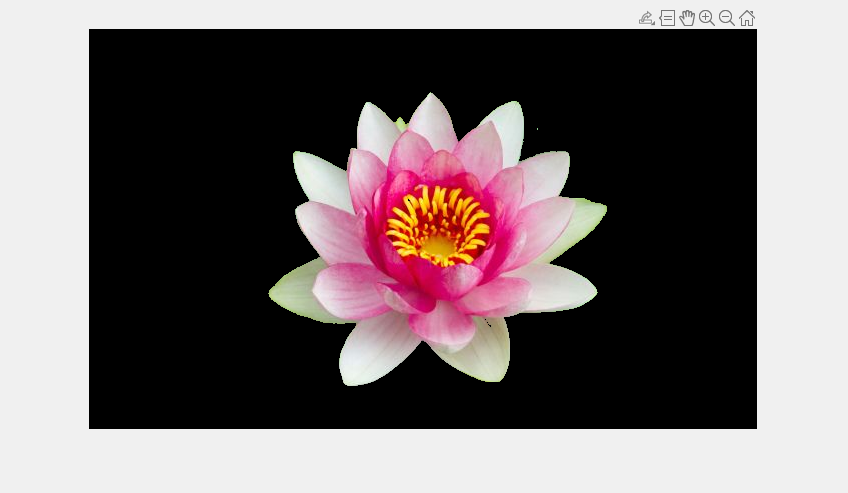

[f c p] = size(I);

% mascara de la seleccio rect
MASK = false([f, c]);
MASK(rect(2):rect(2)+rect(4),rect(1):rect(1)+rect(3)) = 1;
%imshow(MASK);

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);

O = [R(:), G(:), B(:)];
k = 8;
[C, Centroide] = kmeans(double(O),k);  % segon paràmetre indica el nombre de classes
C = reshape(C,[f c]);
%RGB = label2rgb(C);
%imshow(RGB);


in = zeros(8,1); % indica els pixels de cada etiqueta que apareixen a fora del rectangle
out = zeros(8,1); % indica els pixels de cada etiqueta que apareixen a dins del rectangle

for i = 1:f
   for j = 1:c
        if (MASK(i,j) == 0) 
            out(C(i,j),1) = out(C(i,j),1) + 1;
        else
            in(C(i,j),1) = in(C(i,j),1) + 1;
        end
   end
end

RGB2 = uint8(zeros(f, c));
for i = 1:f
    for j = 1:c
        if in(C(i,j),1) > out(C(i,j),1)
            RGB2(i,j,1) = I(i,j,1);
            RGB2(i,j,2) = I(i,j,2);
            RGB2(i,j,3) = I(i,j,3);
        end
    end
end
imshow(RGB2);          